# Script to analyze PSC event data from pclamp

REMEMBER TO PULL AT THE BEGINNING OF EVERY SESSION AND PUSH AT THE END IF CODE CHANGES!!!!

## Analyze Synaptic currents

close all
clear

% Let's start by loading the matrix with the parameters (i.e. conductances)
% of zero error models found by the algorithm
Sham = Load_Params;
HFHI = Load_Params;

% PLOT FEATS% 
%% Savfe features for plotting
writetable(Sham.Feats.FeatsTable(:,'IV_Slope'),'ShamIVSlope.csv')
writetable(Sham.Feats.FeatsTable(:,'Rheo'),'ShamRheobase.csv')
writetable(HFHI.Feats.FeatsTable(:,'IV_Slope'),'HFHIIVSlope.csv')
writetable(HFHI.Feats.FeatsTable(:,'Rheo'),'HFHIRheobase.csv')

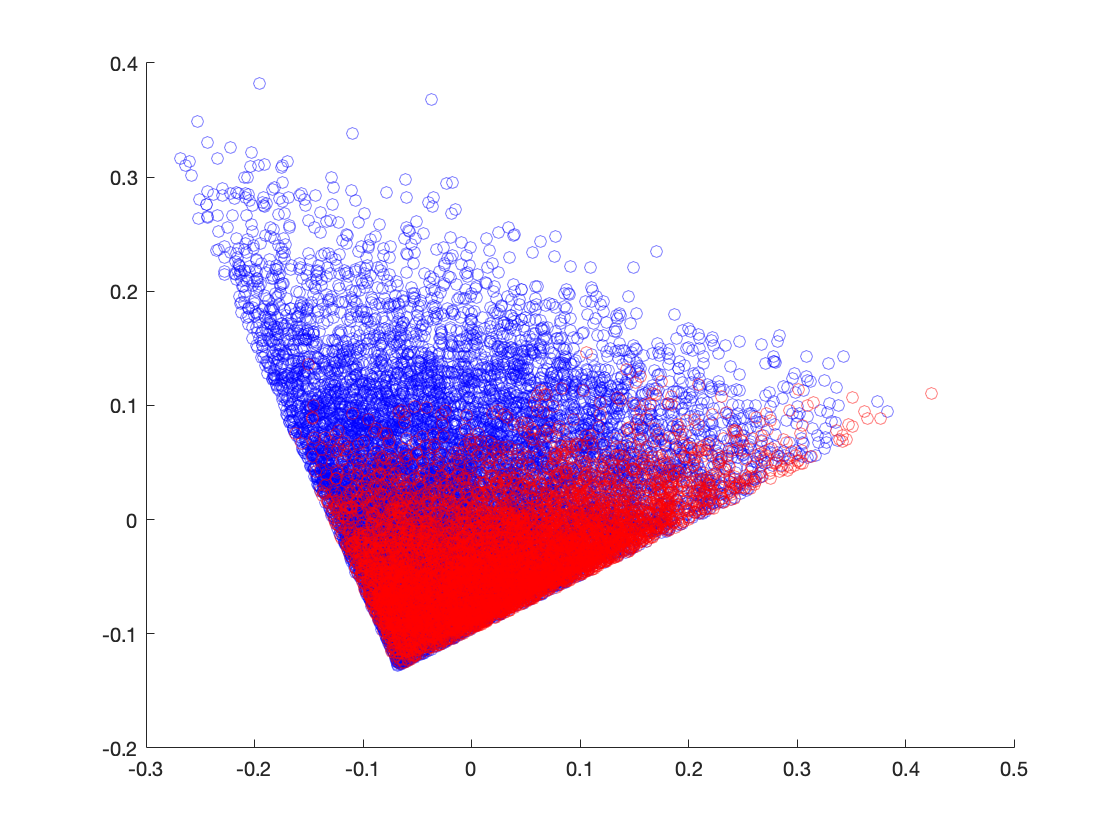


% RUN PCA% 
RunPCA(Sham,HFHI);  

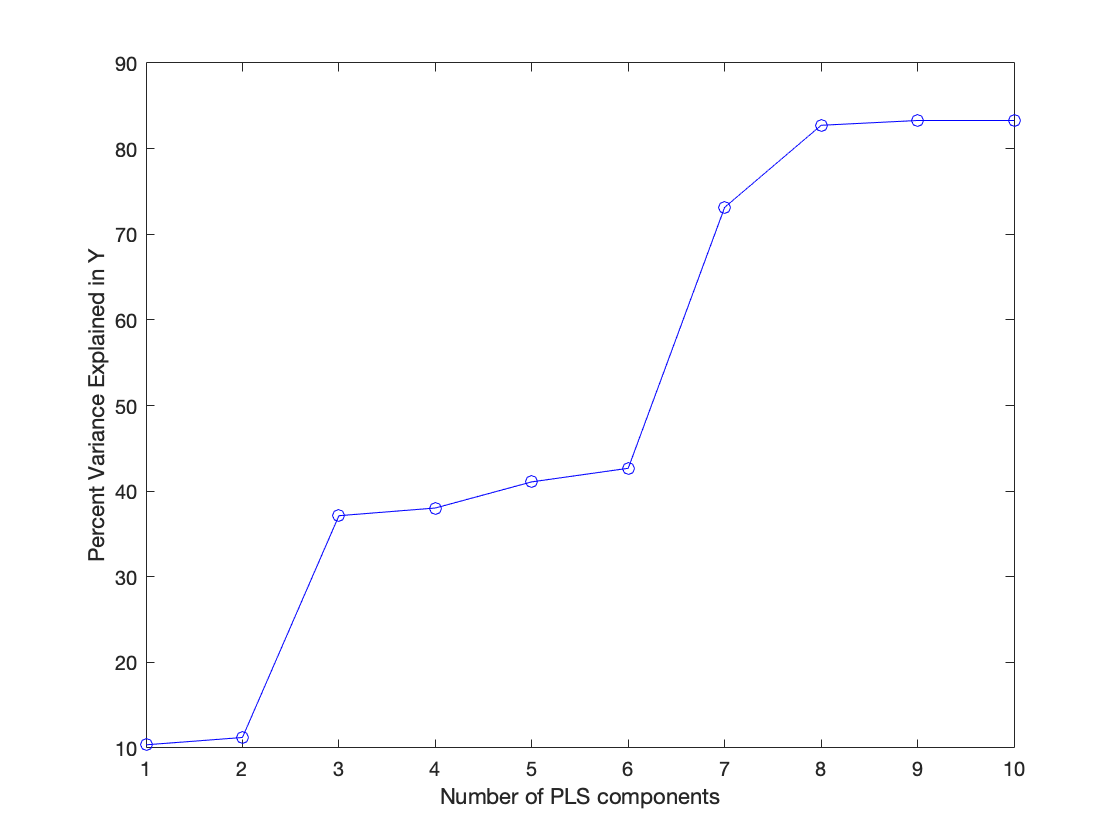

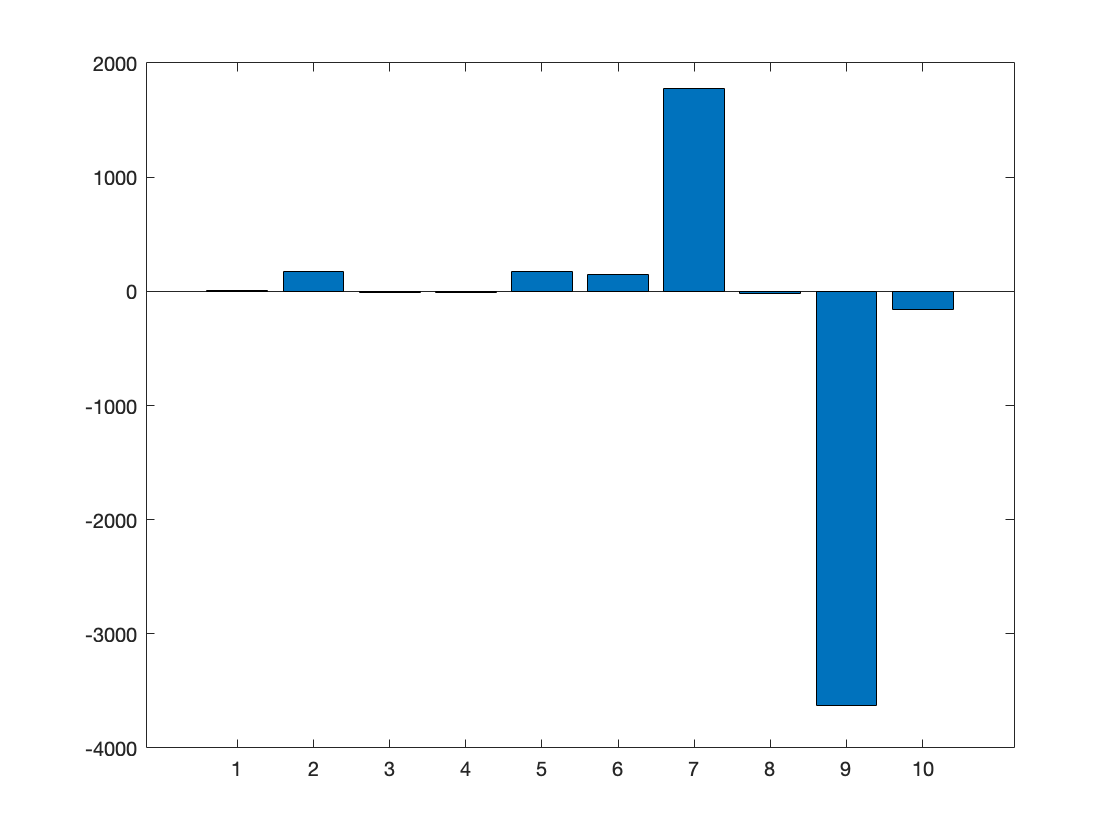

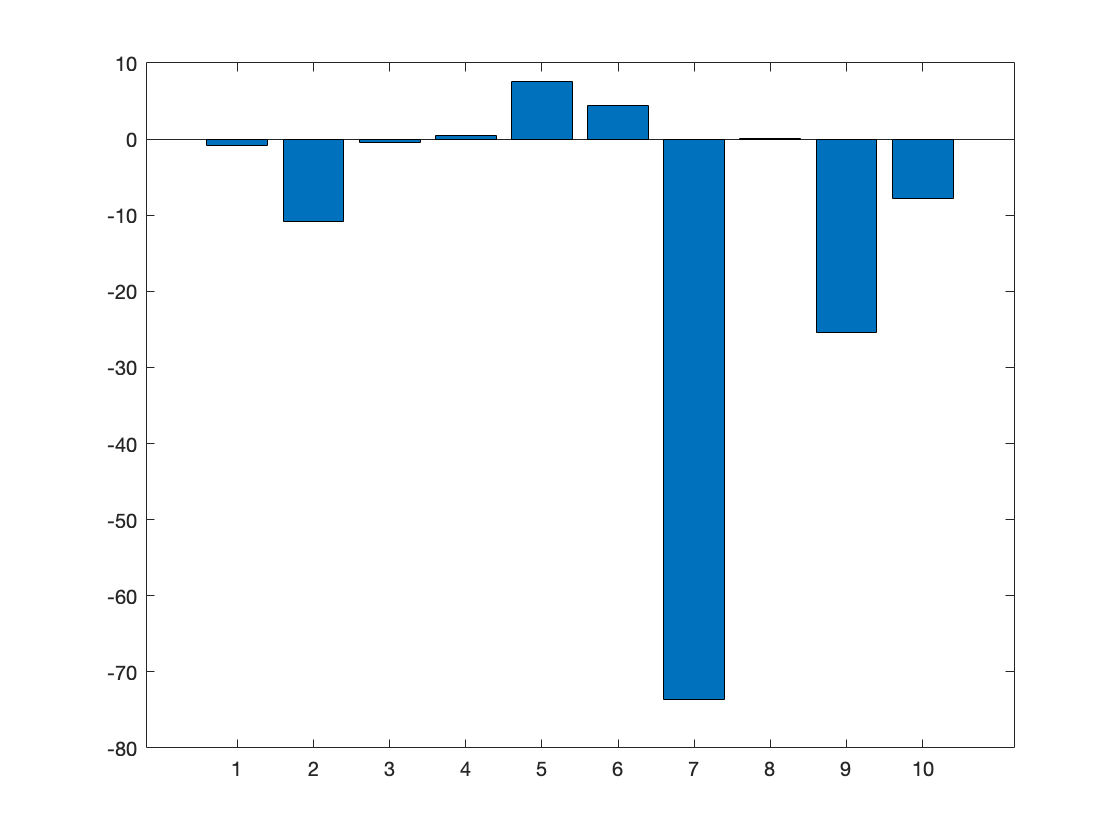

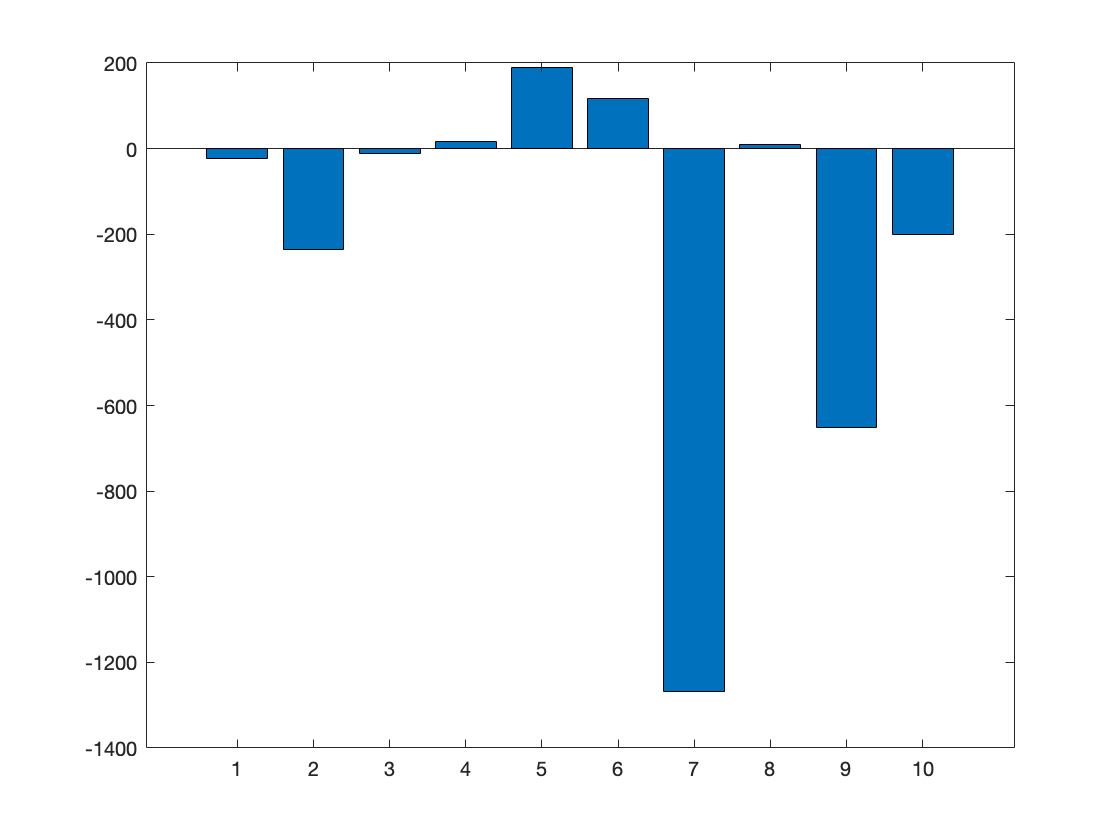

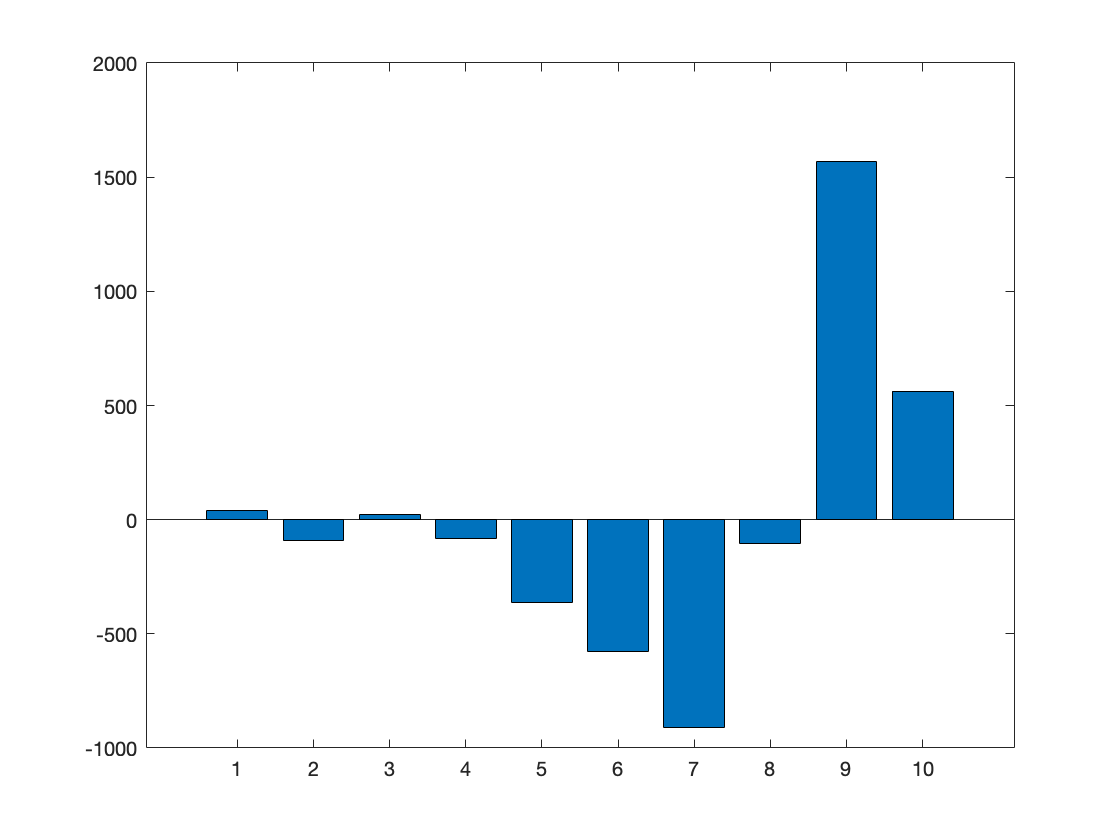

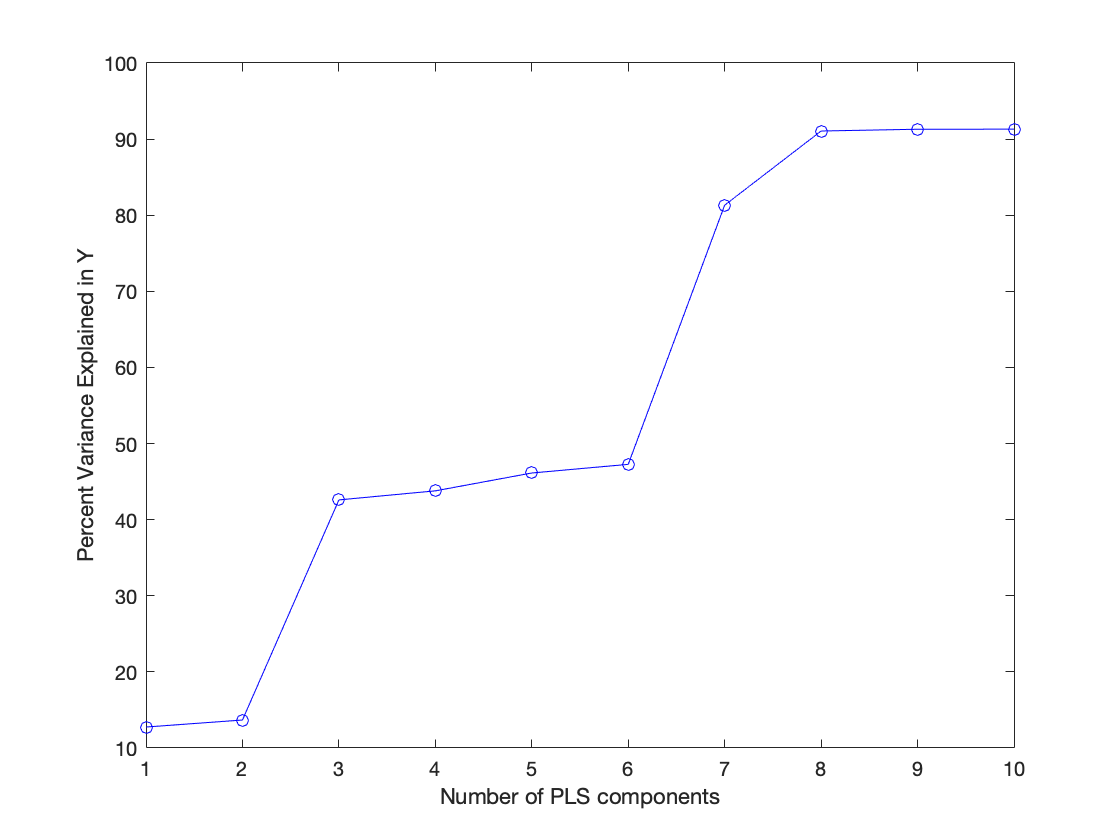

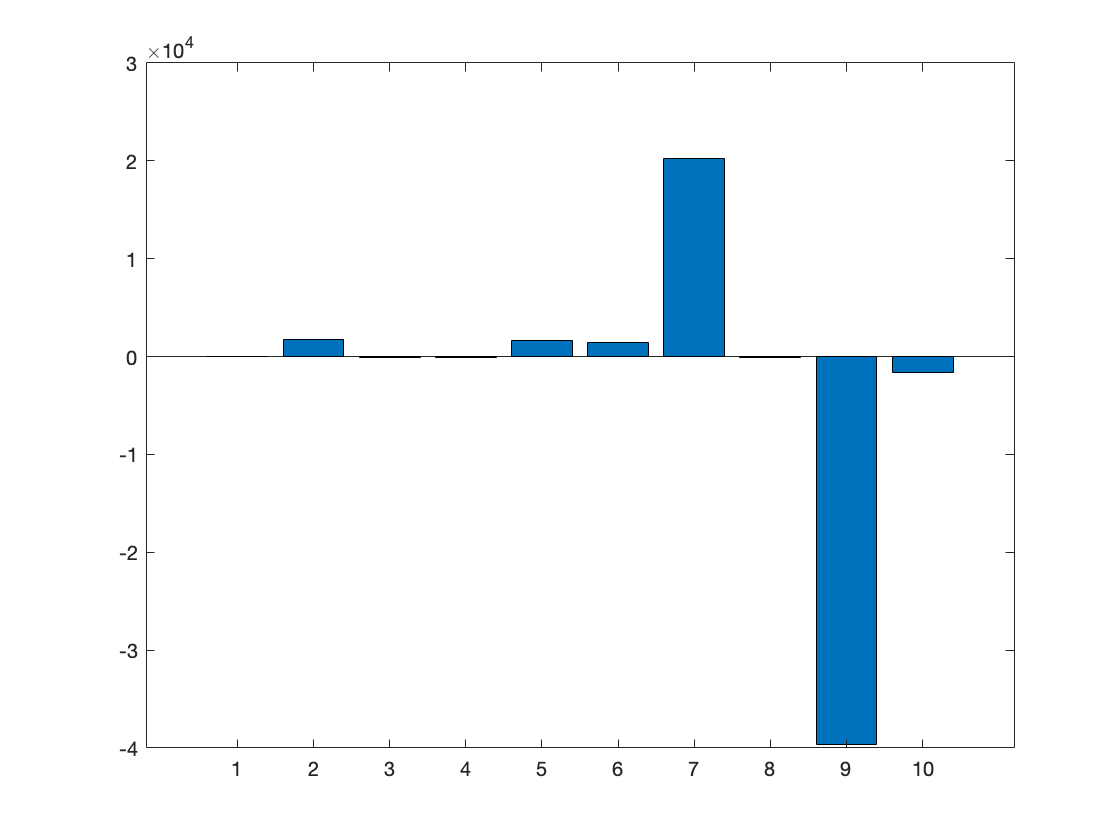

h =   1×3 Axes array:

    Axes    Axes    Axes


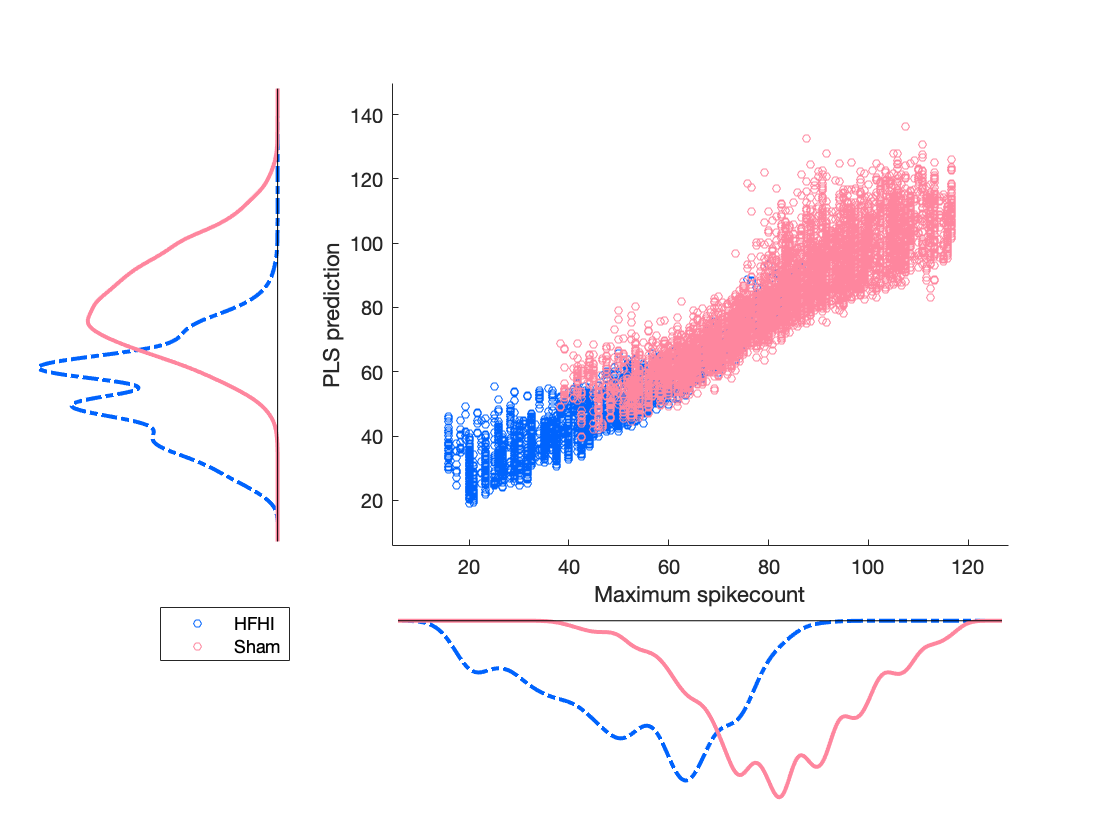

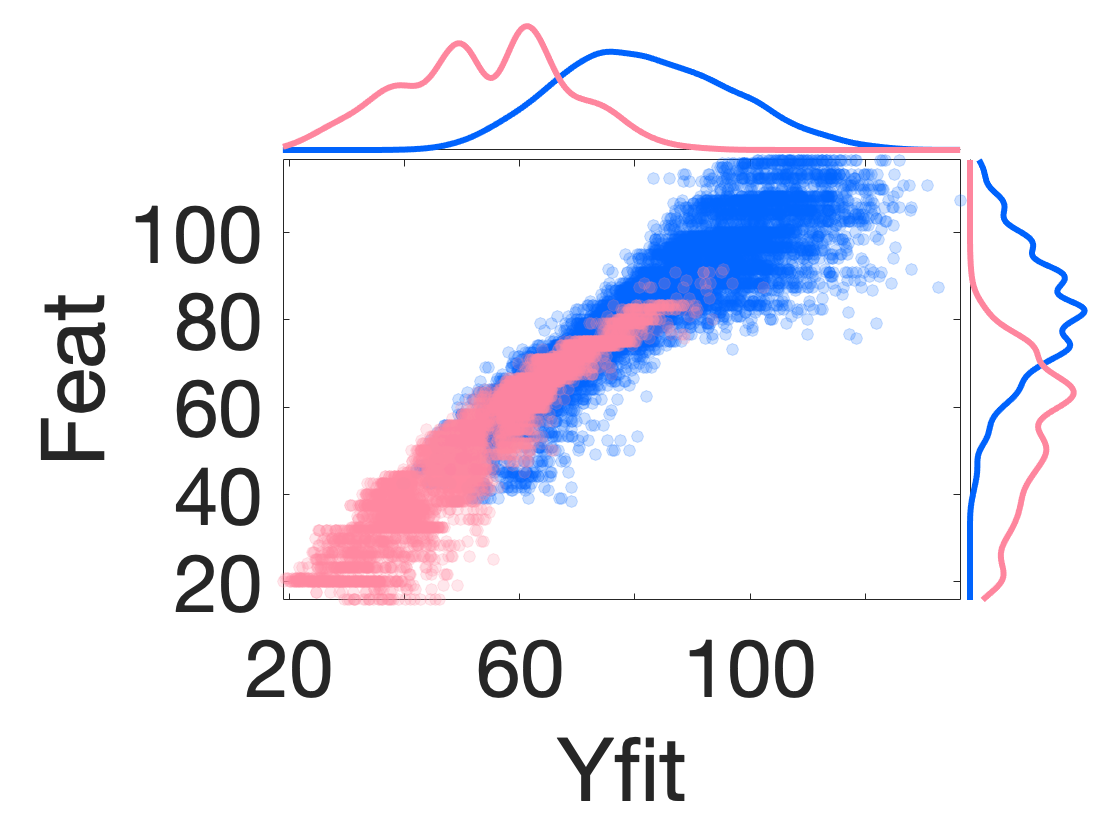

% RUN PSLR% 
RunPLSR(Sham,HFHI);